clear variables;
close all;

eta0 = 800;
etaDot0 = -70;
eta2Dot0 = eta0 ^ 2 / (2*eta0);

etak = 20;
etaDotk = -2;
eta2Dotk = 0;

T = 24;
g = -9.8;
dt = 0.01;
t = 0:dt:T;
N = numel(t);

%   Получение коэффициентов по координате Эта

    [coefEta0, coefEta1, coefEta2, coefEta3, coefEta4, coefEta5] = getCoefficient(eta0, etaDot0, eta2Dot0, etak, etaDotk, eta2Dotk, T);

%   pathEta - траектория пути по Эта
%   speedEta - скорость по Эта
%   boostEta - ускорения по эта
    [pathEta, speedEta, boostEta] = getPathSpeedBoost(coefEta0, coefEta1, coefEta2, coefEta3, coefEta4, coefEta5, t, N);

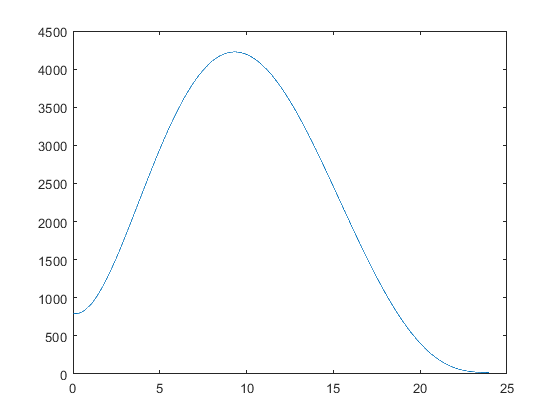

plot(t, pathEta)

function [coef0, coef1, coef2, coef3, coef4, coef5] = getCoefficient(pathInit, speedInit, boostInit, pathFin, speedFin, boostFin, T)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here
    coef0 = pathInit;
    coef1 = speedInit;
    coef2 = boostInit/2;
    coef3 = boostFin /(2 * T) - (6 * speedInit) / T ^ 2 - (3 * boostInit)/(2*T) - (4*speedFin)/T^2 - (10*pathInit)/T^3 + (10*pathFin)/T^3;
    coef4 = (15 * pathInit)/T^4 + (8 * speedInit) / T ^ 3 + (3 * boostInit)/(2*T^2) + (7*speedFin)/T^3 - boostFin/T^2 - (15*pathFin)/T ^ 4;
    coef5 = boostFin / (2 * T ^ 3) - (3 * speedInit) / T ^ 4 - boostInit / (2 * T ^ 3) - (3 * speedFin) / T ^ 4 - (6 * pathInit) / T ^ 5 + (6 * pathFin) / T ^ 5;
end
function [path, speed, boost] = getPathSpeedBoost(a0, a1, a2, a3, a4, a5, t, N)
%Функция getPathSpeedBoost принимает в качестве аргументов коэффициенты
%a0-a5, t - вектор времени, N - количество точек
    path = zeros(1, N);
    speed = zeros(1, N);
    boost = zeros(1, N);
    for i = 1:N
        path(1, i) = a0 + a1*t(1, i) + a2*t(1, i)^2 + a3*t(1, i)^3 + a4*t(1, i)^4 + a5*t(1, i)^5;
        speed(1, i) = a1 + 2*a2*t(1, i) + 3*a3*t(1, i)^2 + 4*a4*t(1, i)^3 + 5*a5*t(1, i)^4;
        boost(1, i) = 2*a2 + 6*a3*t(1, i) + 12*a4*t(1, i)^2 + 20*a5*t(1, i)^3;
    end
end